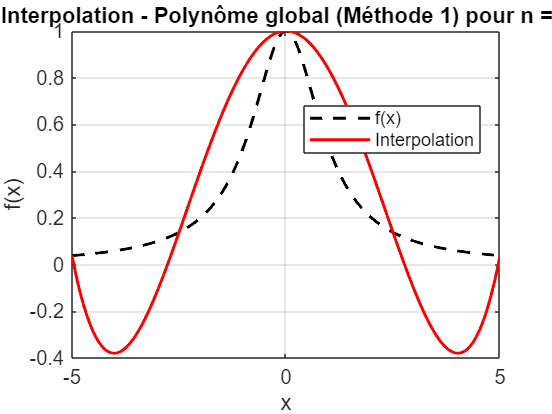

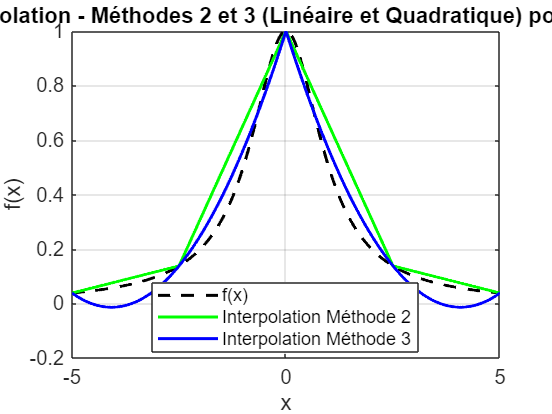

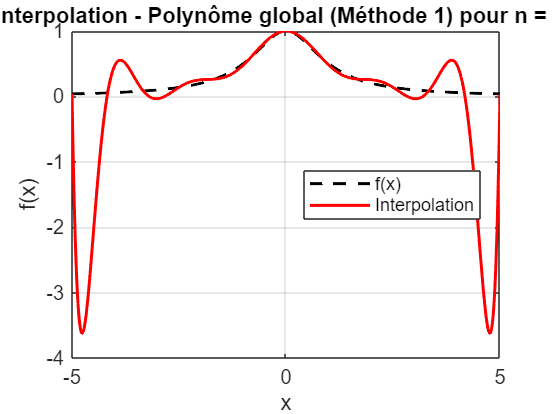

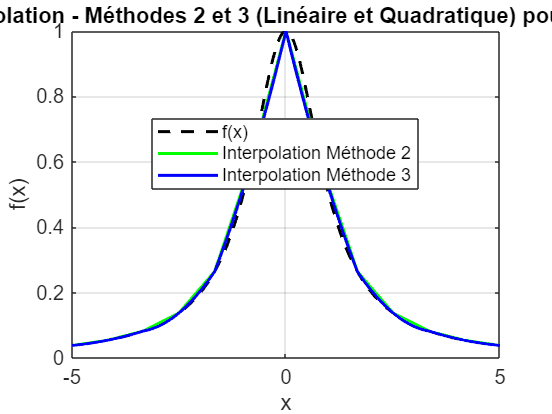

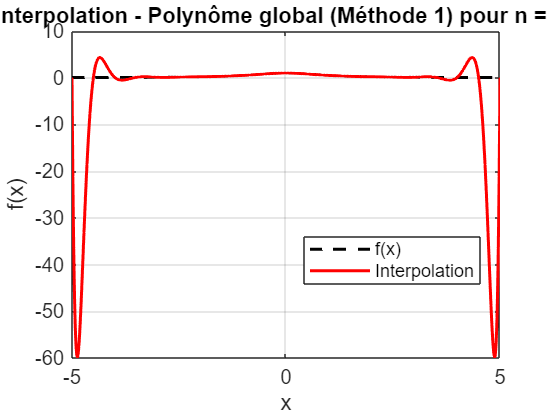

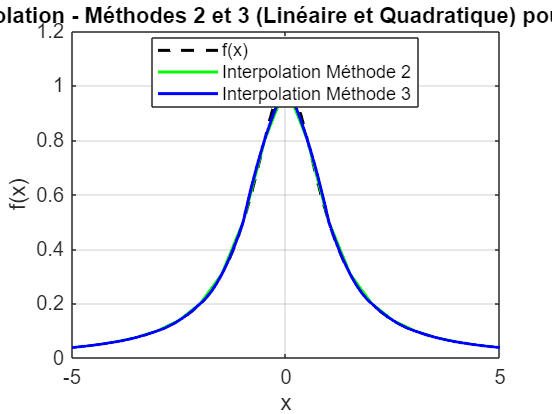


% Question 1:

% a et b)
% Définition de la fonction f
f = @(x) 1 ./ (1 + x.^2);

n_values = [4, 12, 20];
num_graphics = length(n_values);

% On creer un vecteur pour les erreurs absolues
errors = zeros(num_graphics, 1001, 3);

for k = 1:num_graphics
    n = n_values(k);
    
    % Calcule des points d'interpolation
    x_i = linspace(-5, 5, n + 1); % Nœuds équidistants
    y_i = f(x_i); % Valeurs de f aux nœuds

    x_plot = linspace(-5, 5, 1001);
    y_plot = f(x_plot);

    % Méthode 1 : Polynôme global de degré n (polyfit)
    p_coeff = polyfit(x_i, y_i, n);  
    y_interp1 = polyval(p_coeff, x_plot); 


    % Méthode 2 : Interpolation linéaire par morceaux
    breaks_lin = x_i;  
    coefs_lin = zeros(n, 2);  
    for i = 1:n
        % Coefficients du polynôme linéaire
        p = polyfit(x_i(i:i+1), y_i(i:i+1), 1);

        % On stock les coefficients dans la matrice selon leurs relations
        % avec les coefficients Pj de polyfit:
        coefs_lin(i, 1) = p(1);  
        coefs_lin(i, 2) = p(2) + coefs_lin(i, 1) * x_i(i);  % c_{i2} = p2 + p1 * s_i
    end

    % On creer un polynôme par morceaux à partir des coefficients
    pp_lin = mkpp(breaks_lin, coefs_lin);  
    y_interp2 = ppval(pp_lin, x_plot);  


    % Méthode 3 : Interpolation quadratique par morceaux
    breaks_quad = x_i(1:2:end);
    coefs_quad = zeros(n/2, 3);  % Coefficients pour chaque intervalle (quadratique)

    for i = 1:2:n-1
        p = polyfit(x_i(i:i+2), y_i(i:i+2), 2);
        
        % Relations entre les coefficients cij et Pj de polyfit
        s_n = x_i(i);
        coefs_quad((i+1)/2, 1) = p(1);  % c_{i1} = p1
        coefs_quad((i+1)/2, 2) = p(2) + 2 * p(1) * s_n;  % c_{i2} = p2 + 2 * p1 * s_n
        coefs_quad((i+1)/2, 3) = p(3) + p(2) * s_n + p(1) * s_n^2;  % c_{i3}
    end

    pp_quad = mkpp(breaks_quad, coefs_quad);  
    y_interp3 = ppval(pp_quad, x_plot);  

    % Graphiques pour la méthode 1:
    figure;

    % Graphique : Interpolation Méthode 1 avec n = 4, 12, 20
    plot(x_plot, y_plot, 'k--', 'LineWidth', 1.5); hold on;  
    plot(x_plot, y_interp1, 'r-', 'LineWidth', 1.5);  
    title(['Interpolation - Polynôme global (Méthode 1) pour n = ' num2str(n)]);
    xlabel('x');
    ylabel('f(x)');
    legend('f(x)', 'Interpolation', 'Location', 'Best');
    grid on;

    % Graphiques pour les méthodes 2 et 3:
    figure;

    plot(x_plot, y_plot, 'k--', 'LineWidth', 1.5); hold on; % Fonction lineaire
    plot(x_plot, y_interp2, 'g-', 'LineWidth', 1.5);  % méthode 2
    plot(x_plot, y_interp3, 'b-', 'LineWidth', 1.5);  % méthode 3
    title(['Interpolation - Méthodes 2 et 3 (Linéaire et Quadratique) pour n = ' num2str(n)]);
    xlabel('x');
    ylabel('f(x)');
    legend('f(x)', 'Interpolation Méthode 2', 'Interpolation Méthode 3', 'Location', 'Best');
    grid on;

    % Calcule des erreurs:
    errors(k, :, 1) = abs(y_plot - y_interp1);  
    errors(k, :, 2) = abs(y_plot - y_interp2);  
    errors(k, :, 3) = abs(y_plot - y_interp3);  
end

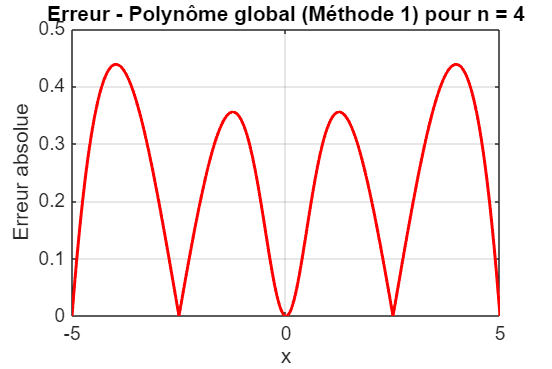

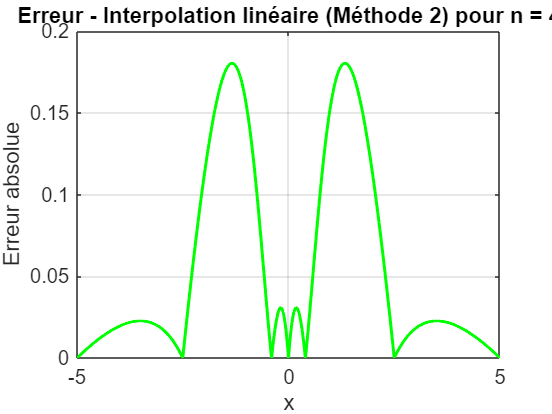

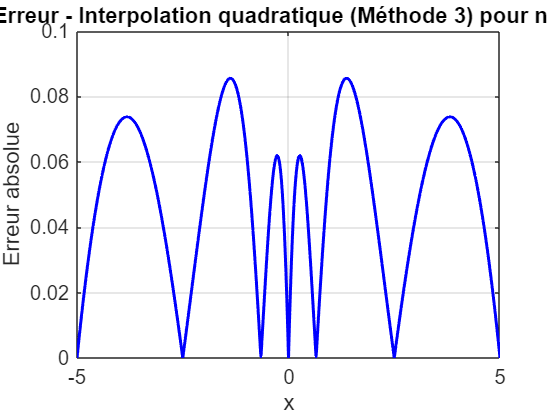

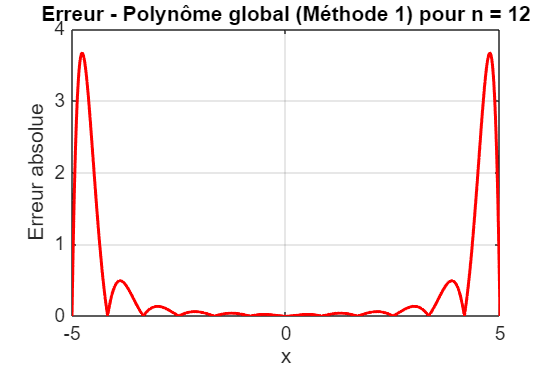

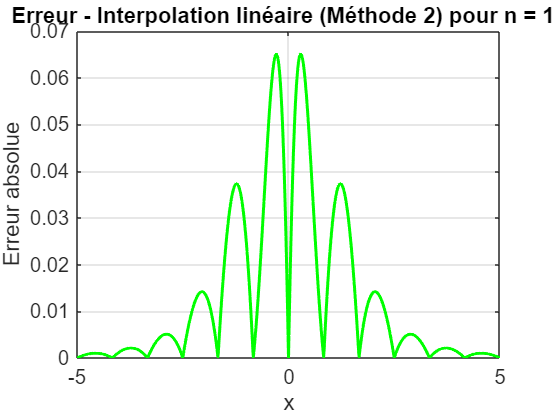

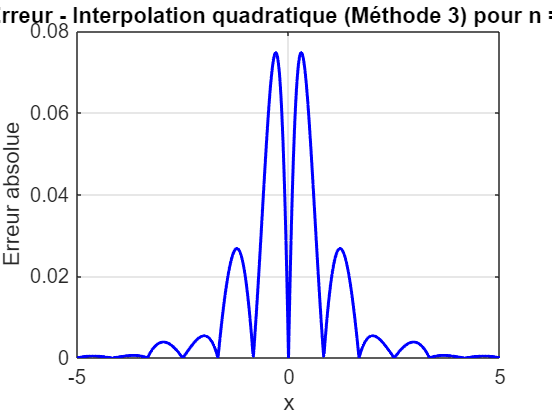

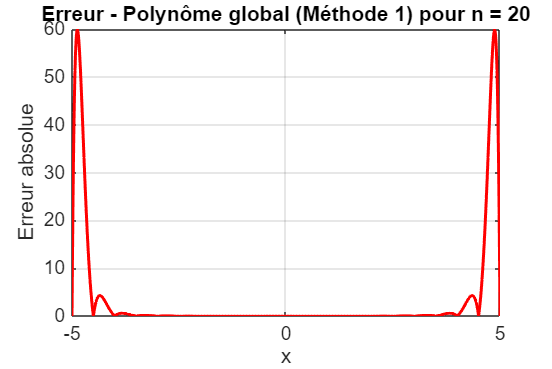

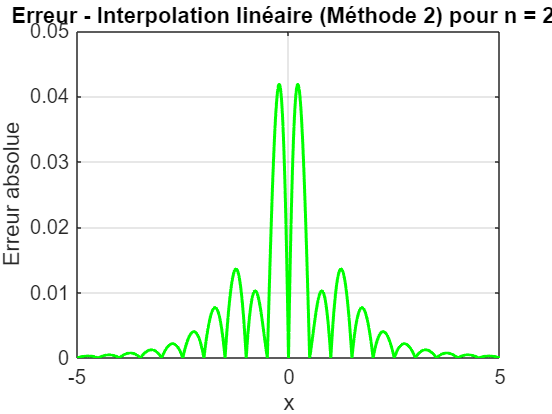


% Question 2 

% a)
% Graphiques pour les erreurs
for k = 1:num_graphics
    n = n_values(k);
    x_plot = linspace(-5, 5, 1001);

    % Graphique : Erreur Méthode 1
    figure;
    plot(x_plot, errors(k, :, 1), 'r-', 'LineWidth', 1.5);
    title(['Erreur - Polynôme global (Méthode 1) pour n = ' num2str(n)]);
    xlabel('x');
    ylabel('Erreur absolue');
    grid on;

    % Graphique : Erreur Méthode 2
    figure;
    plot(x_plot, errors(k, :, 2), 'g-', 'LineWidth', 1.5);
    title(['Erreur - Interpolation linéaire (Méthode 2) pour n = ' num2str(n)]);
    xlabel('x');
    ylabel('Erreur absolue');
    grid on;

    % Graphique : Erreur Méthode 3
    figure;
    plot(x_plot, errors(k, :, 3), 'b-', 'LineWidth', 1.5);
    title(['Erreur - Interpolation quadratique (Méthode 3) pour n = ' num2str(n)]);
    xlabel('x');
    ylabel('Erreur absolue');
    grid on;
end

Lorsqu'on analyse les graphiques d'erreur pour les différentes méthodes d'interpolation, on remarque que l'erreur est effectivement nulle aux points d'interpolation x=xi, ce qui est attendu. Toutefois, on observe également que, pour certaines méthodes et certaines valeurs de nnn, il existe d'autres points où l'erreur est nulle en dehors des nœuds x=xi.

Par exemple, pour n=4, avec les méthodes linéaire et quadratique par morceaux (méthodes 2 et 3), on observe que l'erreur est nulle à 7 points, alors qu'on s'attendrait à ce que cela ne soit vrai qu'aux 5 points d'interpolation. Ces points supplémentaires où l'erreur est nulle se situent autour de x=0.

L'explication serait la symétrie de la fonction f(x) autour de x=0. Cette symétrie pourrait être exploitée par les méthodes d'interpolation par morceaux, notamment la méthode quadratique, ce qui entraînerait des points supplémentaires où l'interpolation coïncide parfaitement avec la fonction réelle, réduisant ainsi l'erreur à zéro à ces points. 

De plus, cela pourrait être liée aux rondeurs numériques dans MATLAB, l'arithmétique en virgule flottante pouvant introduire des erreurs d'arrondi. Ces petites erreurs peuvent parfois annuler l'erreur en dehors des points d'interpolation, particulièrement dans les méthodes où les calculs de coefficients sont complexes, comme ce qu'on a pour les methodes 2 et 3. Cela pourrait expliquer l'apparition de ces zéros supplémentaires, bien qu'ils ne soient pas significatifs sur le plan théorique.

b) Par rapport aux erreurs maximales pour chaque méthode et chaque valeur de n, on peut constater qu'en pratique, les erreurs sont toujours inférieures, parfois même nettement inferieure aux erreurs maximales théoriques. Cela peut s'expliquer par les calculs des bornes qui a ete fait, les bornes superieures pour chaque element n'etait pas forcement les meilleures. De plus les calculs théoriques estiment souvent le pire scénario possible, sans vraiment tenir compte de la façon dont la fonction se comporte dans la réalité. On remarque aussi que nos estimations pour la methode 1 etait bien eloignee de la realite, la ou celles pour les methodes 2 et 3 se rapporocher plus de la pratique

Donc, même si les bornes théoriques sont utiles comme référence, elles ne montrent pas toujours ce qui se passe vraiment quand on applique les méthodes d'interpolation sur une fonction donnée.

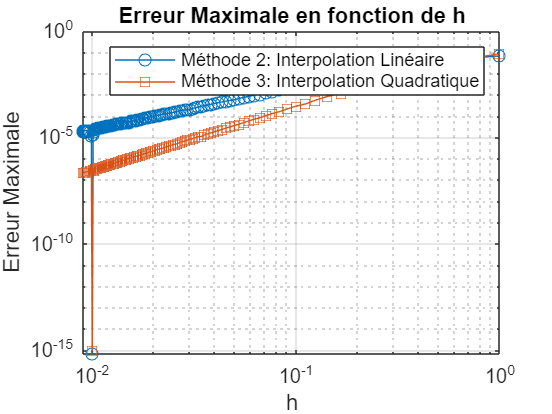


% Question 3:
n_values = 10:10:1110; 
num_n = length(n_values);

errmax = zeros(num_n, 2);
xx = linspace(-5, 5, 1001);

for k = 1:num_n
    n = n_values(k);
    
    % Points d'interpolation:
    x_i = linspace(-5, 5, n + 1); 
    y_i = f(x_i); 

    % Méthode 2 : Interpolation linéaire par morceaux
    breaks_lin = x_i;  
    coefs_lin = zeros(n, 2);  

    for i = 1:n
        p = polyfit(x_i(i:i+1), y_i(i:i+1), 1);
        coefs_lin(i, 1) = p(1);  
        coefs_lin(i, 2) = p(2) + coefs_lin(i, 1) * x_i(i);  
    end

    pp_lin = mkpp(breaks_lin, coefs_lin);  
    y_interp2 = ppval(pp_lin, xx);  

    % Calcule de l'erreur maximale pour la méthode 2
    errmax(k, 1) = max(abs(f(xx) - y_interp2));

    % Méthode 3 : Interpolation quadratique par morceaux
    breaks_quad = x_i(1:2:end);
    coefs_quad = zeros(floor(n/2), 3);  

    for i = 1:2:n-1  
        p = polyfit(x_i(i:i+2), y_i(i:i+2), 2);
        s_n = x_i(i);  
        coefs_quad((i+1)/2, 1) = p(1);  
        coefs_quad((i+1)/2, 2) = p(2) + 2 * p(1) * s_n;  
        coefs_quad((i+1)/2, 3) = p(3) + p(2) * s_n + p(1) * s_n^2;  
    end

    pp_quad = mkpp(breaks_quad, coefs_quad);  
    y_interp3 = ppval(pp_quad, xx);  

    % Calcule de l'erreur maximale pour la méthode 3
    errmax(k, 2) = max(abs(f(xx) - y_interp3));
end

% Calculer h en fonction de n
h = 10 ./ n_values;  % h = 10 / n

% Tracer des erreurs maximales
figure;
loglog(h, errmax(:, 1), '-o', 'DisplayName', 'Méthode 2: Interpolation Linéaire');
hold on;
loglog(h, errmax(:, 2), '-s', 'DisplayName', 'Méthode 3: Interpolation Quadratique');
xlabel('h');
ylabel('Erreur Maximale');
title('Erreur Maximale en fonction de h');
legend('show');
grid on;


% Calcul des logarithmes
log_h = log(h);
log_errmax_lin = log(errmax(:, 1));
log_errmax_quad = log(errmax(:, 2));


% Ajustement linéaire pour la méthode 2 
pente_lin = polyfit(log_h, log_errmax_lin, 1);

% Ajustement linéaire pour la méthode 3 
pente_quad = polyfit(log_h, log_errmax_quad, 1);

% Affichage des pentes
fprintf('Pente pour la méthode 2 (Interpolation linéaire) : %.4f\n', pente_lin(1));

Pente pour la méthode 2 (Interpolation linéaire) : 2.1702


fprintf('Pente pour la méthode 3 (Interpolation quadratique) : %.4f\n', pente_quad(1));

Pente pour la méthode 3 (Interpolation quadratique) : 3.0991


Commenter:

En analysant les pentes obtenues à partir des ajustements linéaires des erreurs maximales pour les deux méthodes d'interpolation, nous pouvons observer leurs comportements. 

Pour la methode 2 la pente calculée est d'environ 2. Cela indique une convergence des erreurs maximales proportionnelle à h^2, ce qui est typique pour une méthode d'interpolation linéaire. En effet, l'erreur d'approximation d'une interpolation linéaire diminue avec le carré de la taille de l'intervalle h, ce qui souligne que cette méthode est relativement efficace pour des tailles d'intervalle réduites.

La ou pour la methode 3, la pente est d'environ 3, ce qui suggère une convergence proportionnelle à h^3. Cette observation est cohérente avec le comportement attendu d'une interpolation quadratique, qui offre une précision améliorée par rapport à l'interpolation linéaire.